#  **3D image processing** **using three-dimensional Element wise Addition**

This example shows how to process two colour image using the three-dimensional Element wise Addition.

Read an image into the workspace, then convert the image to double.



[X,map] = imread('kotatko.tiff');
if ~isempty(map)
    Im1 = ind2rgb(X,map);
end
[Y,map] = imread('water.tiff');
if ~isempty(map)
    Im2 = ind2rgb(Y,map);
end

Perform a 3D elementwise addition of the colour images using the ELA_CUDA_3D  function.

K = ELA_CUDA_3D(single(Im1),single(Im2), 0.5, 1);

Display the original colour image alongside the processed image.

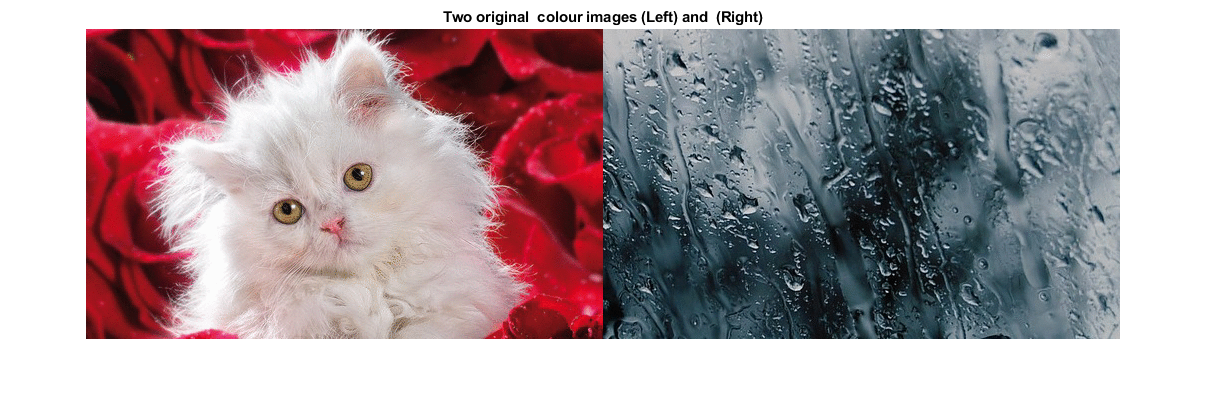

figure
imshowpair(Im1,Im2,'montage')
title('Two original  colour images (Left) and  (Right)');

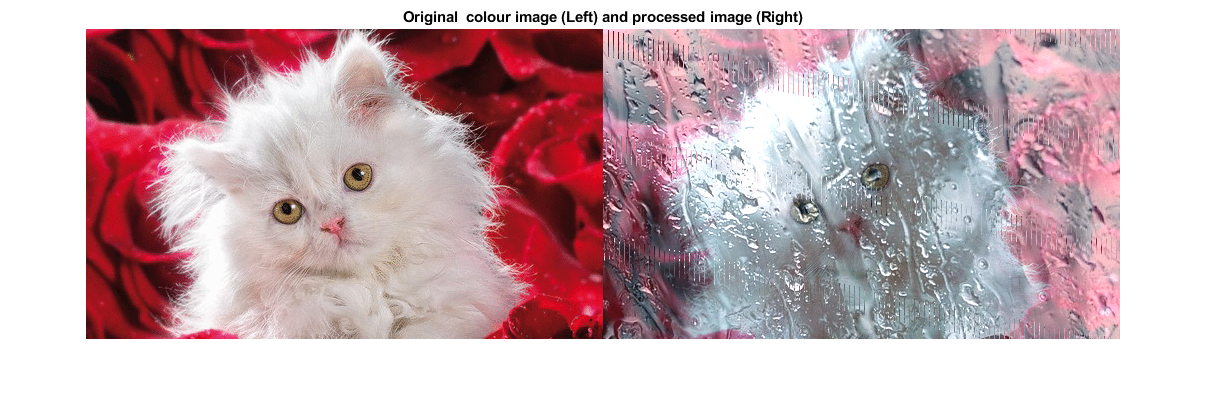

figure
imshowpair(Im1,K,'montage')

title('Original  colour image (Left) and processed image (Right)');